# Design of a Controller for a Minumum Phase  Process with Uncertain Steady-State Gain

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

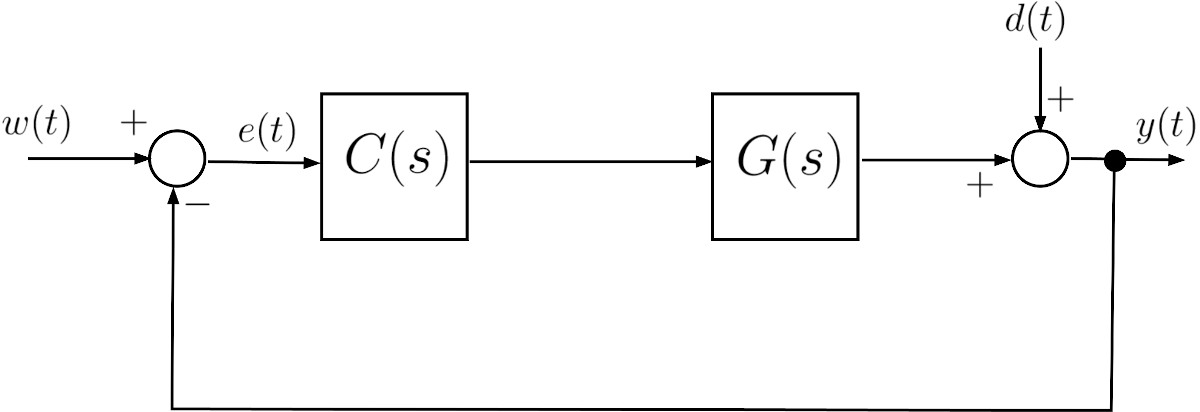	

where $G(s)$ is given by                


$$G(s) = \mu_G \frac{1+5\,s}{(1+16\,s)(1+17\,s)}\;,\quad \mu_G \in \left[0.35\,,\; 4.25 \right]$$
	

## **Question**		

**Q1**: Assume $d(t) = 0 \,\forall t$. Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $\left| e(\infty)\right| =0$ for $w(t) =  \mathbf{1}(t)$, where $\mathbf{1}(t)$ denotes the unit step function;

- The phase margin satisfies $\varphi_m \ge 50^{\degree}$.

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))


### Requirements Analysis & Design Strategy

**Requirement (Q1.1): **This requirement implies that the **open-loop transfer function** should be of **type **$\mathbf{g=1}$. An integrator has to be added by the controller


$$C(s) = \frac{\mu_C}{s} \quad \Longrightarrow \quad L(s) = \mu_C\, \mu_G\, \frac{(1+5\,s)}{s\,(1+16\,s)(1+17\,s)}$$


**Requirement (Q1.2)**: A preliminary Bode diagram of the frequency response $L(j\omega)$ could help determine the feasibility of a solution meeting the requirement (Q1.2).  

- The Bode phase diagram is unaffected by any positive value we assign to the controller gain constant $\mu_C$. 

- Similarly, it is unaffected by the positive but uncertain value of the steady-state gain $\mu_G$ of $G(s)$. 

- We can assign a unitary value to both the gains, plot the Bode diagrams, and analyse the phase plot for the feasibility of the controller design.

**The preliminary Bode Diagrams**

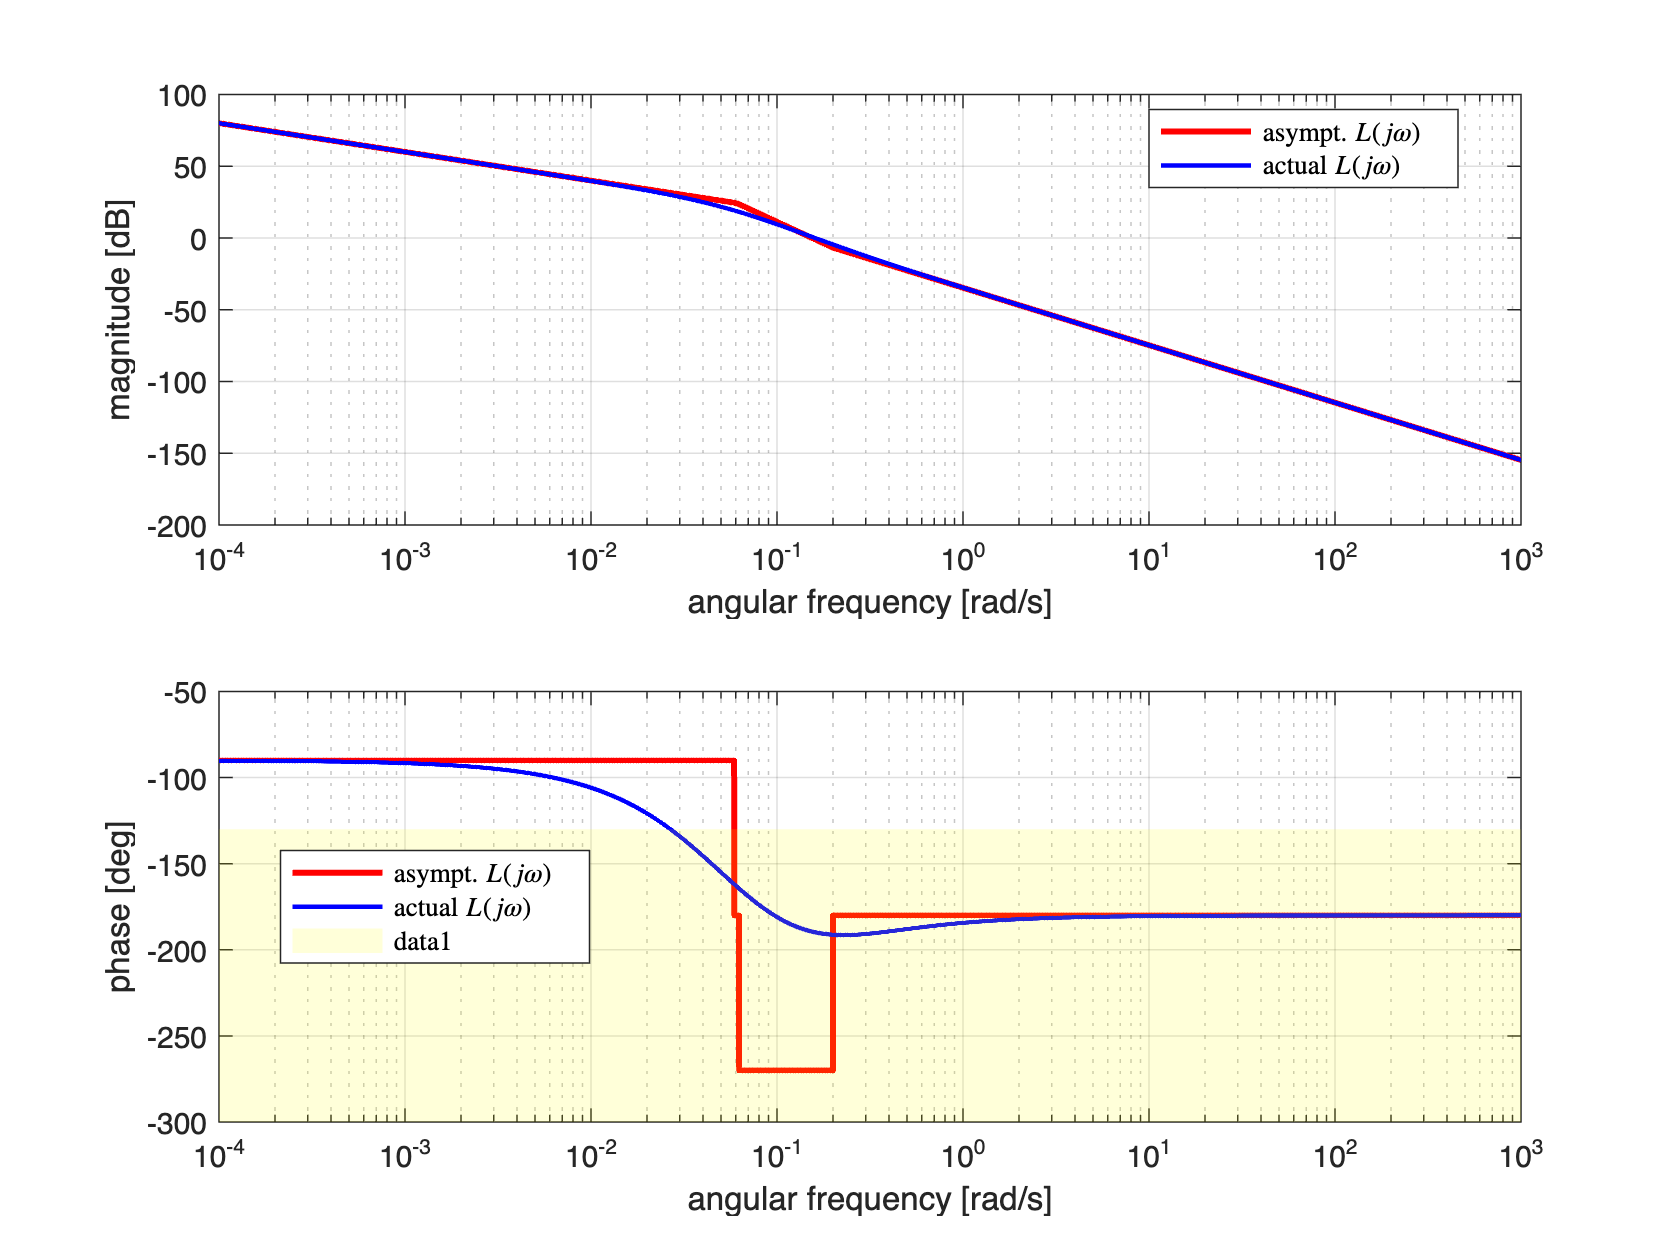


% let's define the transfer function builder element
s=tf('s');

pre_muC =1;  % preliminar gain for the controller
pre_muG = 1; % preliminar gain for the process

pre_C1s = pre_muC/(s);                        % the preliminary controller C(s)
pre_Gs = pre_muG*(1+5*s)/((1+16*s)*(1+17*s)); % the preliminary process G(s)

pre_Ls = pre_C1s*pre_Gs;                      % the preliminary open-loop transfer function L(s) C(s)
                                              % Note: there is no zero/pole
                                              % (or pole/zero)
                                              % simplification, so we don't
                                              % need to use the function
                                              % minreal( )


[ha1, ha2] = drawBodediagrams(pre_Ls);
legend(ha1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
legend(ha2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
phaseM = +50; % the desired minimum phase margin
feas_Ls_Phase = -180+phaseM; % the minimum value of the arg L(j omega) 
                             % to guarantee the feasibility of the design

YLIMS = ylim(ha2);
OMLIMs = xlim(ha2);

% the (Q1.2) constraint
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
PhLIM = feas_Ls_Phase;

Vert1 = [minOmega1 ,  YLIMS(1); minOmega1 ,PhLIM; ...
         maxOmega1 , PhLIM; maxOmega1 , YLIMS(1)];
Faces1 = [1  2  3  4];
hold on;
patch(ha2, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

#### Design Strategy

- As you can notice, keeping the controller as $C(s) = \frac{\mu_C}{s}$, the design problem is **feasible** only if the crossover frequency $\omega_c$ assumes a very low value. That means $\mu_C \ll 1$.

- For example, computing the proper gain value $\mu_C$ to impose the crossover frequency $\omega_c = \frac{1}{100}\;\text{rad/s}$, you will obtain a controller that meets both the requirements. 

- Otherwise, if we would like to guarantee $\omega_c >1$ (to have a faster closed-loop response to a step reference signal), we obtain the feasibility of the design if and only if we modify the controller structure.

- The most straightforward strategy to obtain the feasibility of the controller design, guaranteeing at the same time $\omega_c \ge1$, is to add a zero to the controller transfer function $C(s)$ to "cancel" one of the poles of $G(s)$. With this approach you may verify that


$$C(s) = \mu_C\,\frac{1+17\,s}{s} \;\Longrightarrow \; L(s) = \mu_C\,\mu_G\, \frac{(1+5\,s)}{s\,(1+16\,s)}\; \Longrightarrow  \quad \arg L(j\bar \omega) \underset{\bar\omega \to \infty}{\to} -90^{\degree}$$


            The proposed controller solution is feasible, at least when $\omega_c \gg 5\;\text{rad/s}$.

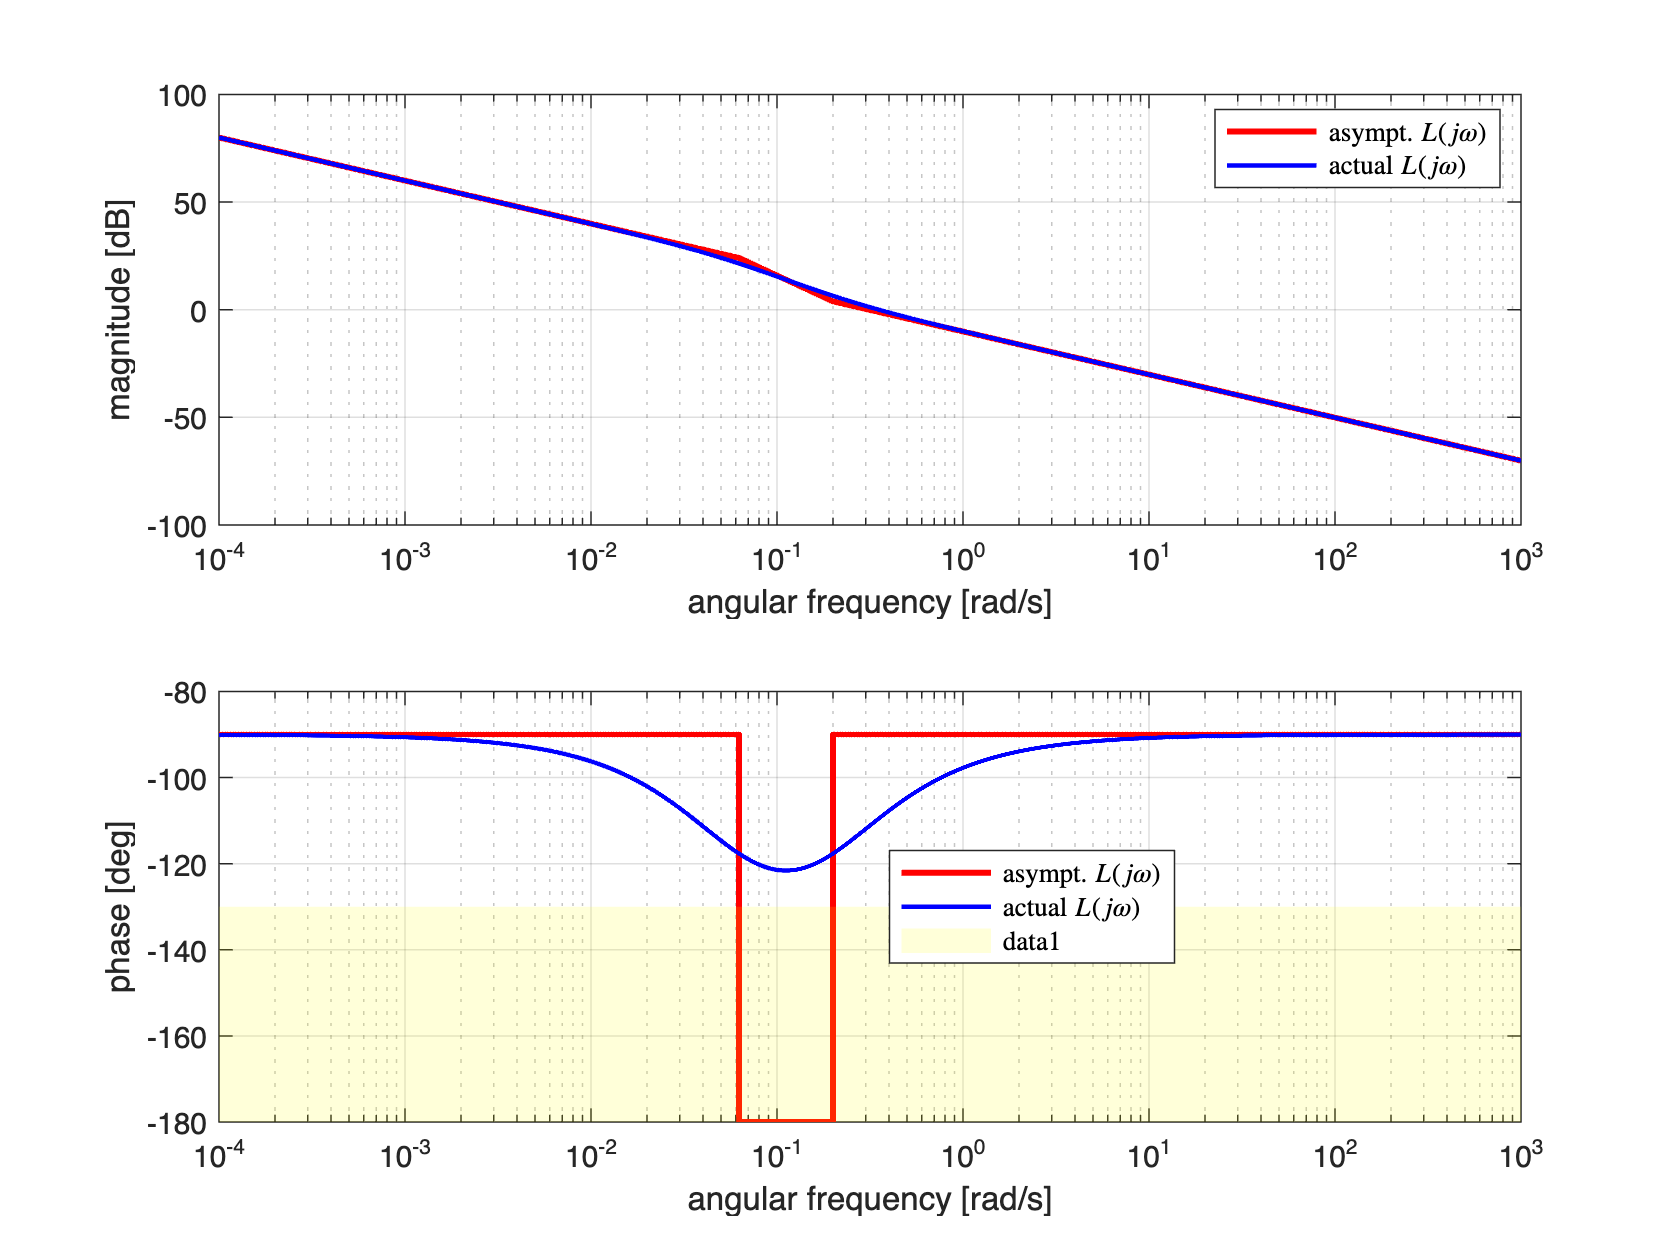

pre_C2s = pre_muC*(1+17*s)/(s);                 % the preliminary controller C(s)
% pre_Gs = pre_muG*(1+5*s)/((1+16*s)*(1+17*s)); % the preliminary process G(s)

pre_Ls = minreal(pre_C2s*pre_Gs);               % the preliminary open-loop transfer function L(s)  
                                              

[ha1, ha2] = drawBodediagrams(pre_Ls);
legend(ha1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
legend(ha2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
phaseM = +50; % the desired minimum phase margin
feas_Ls_Phase = -180+phaseM; % the minimum value of the arg L(j omega) 
                             % to guarantee the feasibility of the design

YLIMS = ylim(ha2);
OMLIMs = xlim(ha2);

% the (Q1.2) constraint
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
PhLIM = feas_Ls_Phase;

Vert1 = [minOmega1 ,  YLIMS(1); minOmega1 ,PhLIM; ...
         maxOmega1 , PhLIM; maxOmega1 , YLIMS(1)];
Faces1 = [1  2  3  4];
hold on;
patch(ha2, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none');

Indeed, as you can notice from analysing the above Bode diagrams, the choice of any value $\bar \omega$ as crossover frequency $\omega_c$ leads to a feasible solution that meets all the requirements.

### A1: Answer to Question Q1

Let's "cancel" the slowest pole of $G(s)$ with a zero in the controller $C(s)$

muC = 1;
Cs = muC*(1+17*s)/s;      % the controller

How to cope with the uncertain gain $\mu_G$?

Consider three different scenarios: 

- the gain $\mu_G$ assumes the minimum admissible value: $\mu_G = 0.35$;

- the gain $\mu_G$ assumes the maximum admissible value: $\mu_G = 4.25$;

- the gain $\mu_G$ assumes an intermediate admissible value: $\mu_G = 1$

Let's compare the corresponding Bode diagrams of the frequency response $L(j\omega)$, assuming, for simplicity, that $\mu_C=1$.

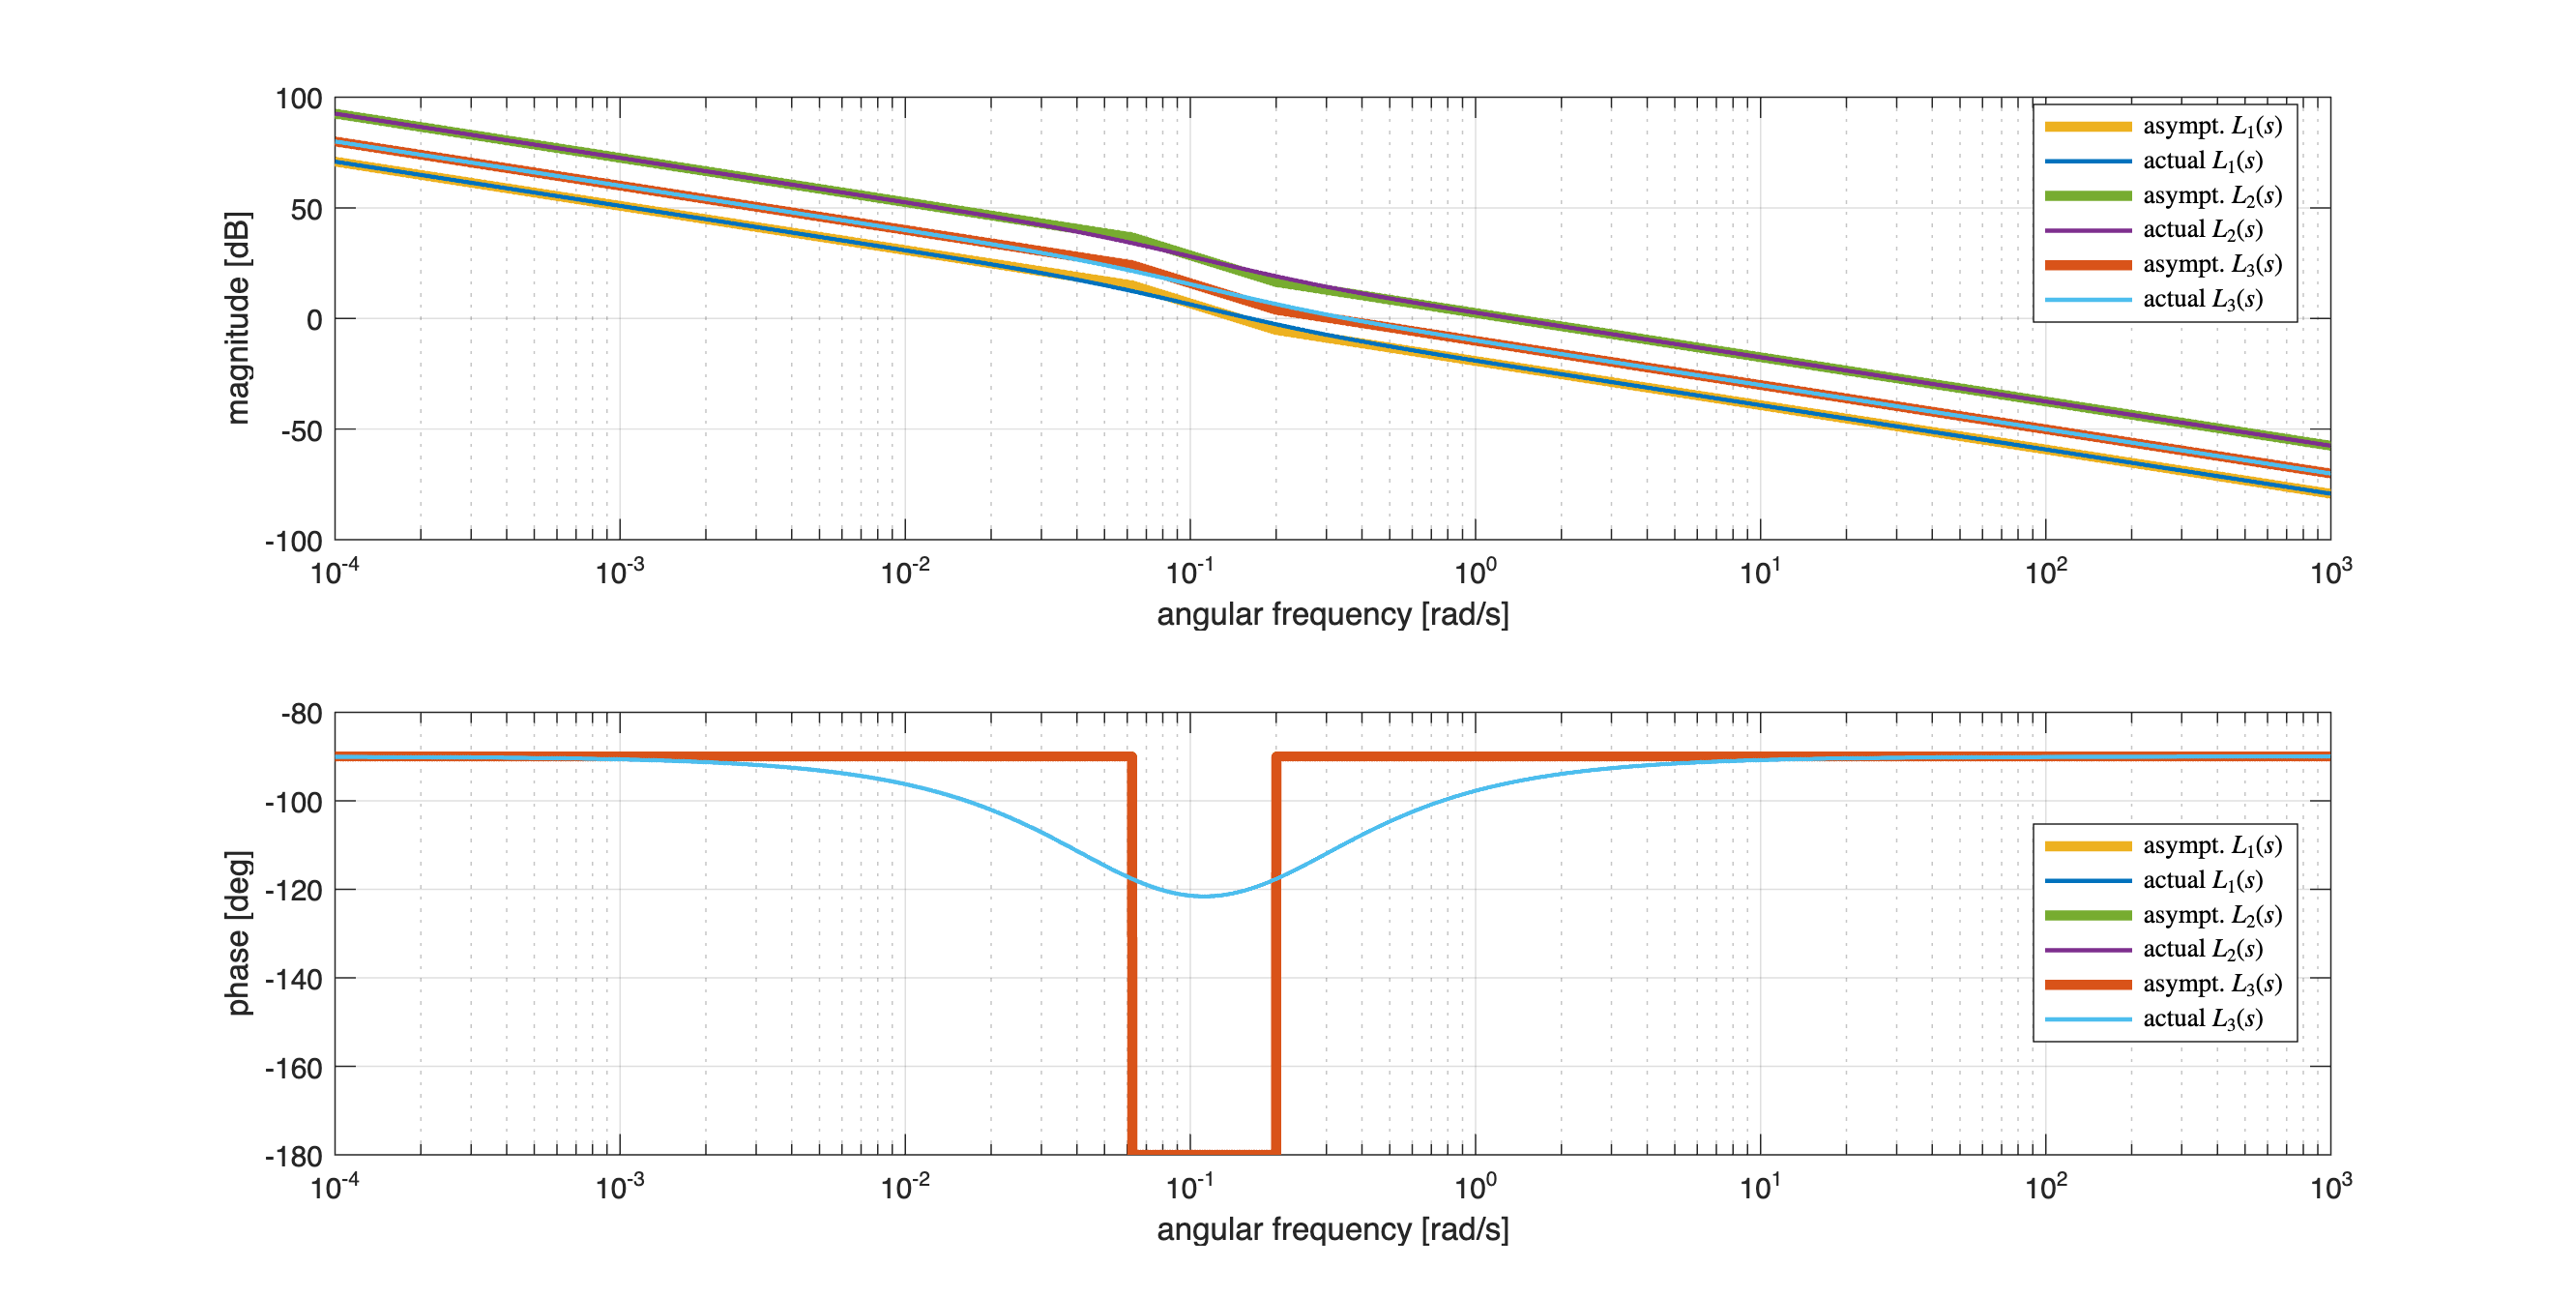

muG1 = 0.35; % the minimum gain
muG2 = 4.25; % the maximum gain
muG3 = 1; % an intermediate value

Gs1 = muG1*(1+5*s)/((1+16*s)*(1+17*s)); 
Gs2 = muG2*(1+5*s)/((1+16*s)*(1+17*s)); 
Gs3 = muG3*(1+5*s)/((1+16*s)*(1+17*s)); 

Ls1 = minreal(Cs*Gs1); 
Ls2 = minreal(Cs*Gs2); 
Ls3 = minreal(Cs*Gs3); 

% the Bode diagrams

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                 

hf = figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.85]);
drawBodediagrams(Ls1, [], Bcolors(2,:) , 3.5, [], Bcolors(1,:) ,1.5, [], hf);
drawBodediagrams(Ls2, [], Bcolors(4,:) , 3.5, [], Bcolors(3,:) ,1.5, [], hf);
[hax1, hax2] = drawBodediagrams(Ls3, [], Bcolors(6,:) , 3.5, [], Bcolors(5,:) ,1.5, [], hf);

legend(hax1, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'best')
legend(hax2, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'best')

When $\mu_G$ increases, the magnitude diagram moves  up, so the crossover frequency $\omega_c$ also increases. We can turn this property to our advantage.

[~, PM1, ~, OMpm1] = margin(Ls1)

PM1 = 60.1088

OMpm1 = 0.1621

[~, PM2, ~, OMpm2] = margin(Ls2)

PM2 = 84.1872

OMpm2 = 1.3414

[~, PM3, ~, OMpm3] = margin(Ls3)

PM3 = 70.5288

OMpm3 = 0.3536

#### Fine Tuning of the Controller using the Control System Designer

Select the controller's gain $\mu_C$ such that, when $\mu_G = 0.35$ the crossover frequency is $\omega_c \ge 1/5\;\text{rad/s}$. Both the requirements are met. In this way, if the effective gain $\mu_g$ assumes a different value in the interval$\left[ 0.35\,,\;4.25\right]$, then the crossover frequency also  increases, and so does the phase margin, i.e., the requirements will still be met.

Select $\bar \omega = 1\;\text{rad/s}$ as the crossover frequency in the case $\mu_G=0.35$ and compute the required gain value $\mu_C$


$$\bar\omega = 1\,\text{rad/s} :\; \left\vert L_1(j\bar\omega)\right\vert = 1 \; \Longrightarrow\;
 \mu_C\,0.35\, \frac{\vert1+j5\vert}{1\,\vert1+j16\vert} \;\Longrightarrow\; 
\mu_c = \frac{\vert1+j16\vert}{0.35\, \vert1+j5\vert} = \frac{100}{35}\,\frac{\sqrt{1+256}}{\sqrt{1+25}} = 
\frac{20}{7}\, \frac{\sqrt{257}}{\sqrt{26}}\approx 8.98$$


Thus the controller $C(s)$


$$C(s) = 8.98\,\frac{1+17\,s}{s}$$


meets all the requirements.

barOmega = 1;
muC = 1/abs(freqresp(Ls1, barOmega))

muC = 8.9828

Cs = muC*(1+17*s)/s;

Consider the three LTI models defined above for the process $G(s)$ and create an array of LTI models using the [`stack`](https://it.mathworks.com/help/control/ref/inputoutputmodel.stack.html) command:

help stack

--- help for InputOutputModel/stack ---

 stack  Stacks input/output models into model array.
 
    M = stack(ARRAYDIM,M1,M2,...) produces an array M of input/output models 
    by stacking the models M1,M2,... along the array dimension ARRAYDIM.  
    All models must have the same number of inputs and outputs and the I/O 
    dimensions are not counted as array dimensions.
 
    For example, if M1 and M2 are two models with the same I/O sizes,
      * stack(1,M1,M2) produces a 2-by-1 array
      * stack(2,M1,M2) produces a 1-by-2 array
      * stack(3,M1,M2) produces a 1-by-1-by-2 array.
 
    You can also use stack to concatenate the model arrays M1,M2,... along
    the array dimension ARRAYDIM.
 
    See also InputOutputModel/horzcat, Input

muG1 = 0.35; % the minimum gain
muG2 = 4.25; % the maximum gain
muG3 = 1; % an intermediate value

Gs1 = muG1*(1+5*s)/((1+16*s)*(1+17*s)); 
Gs2 = muG2*(1+5*s)/((1+16*s)*(1+17*s)); 
Gs3 = muG3*(1+5*s)/((1+16*s)*(1+17*s)); 

Gs = stack(1, Gs1, Gs2, Gs3);

controlSystemDesigner(Gs, Cs); % import plant model and the controller using the usual approach


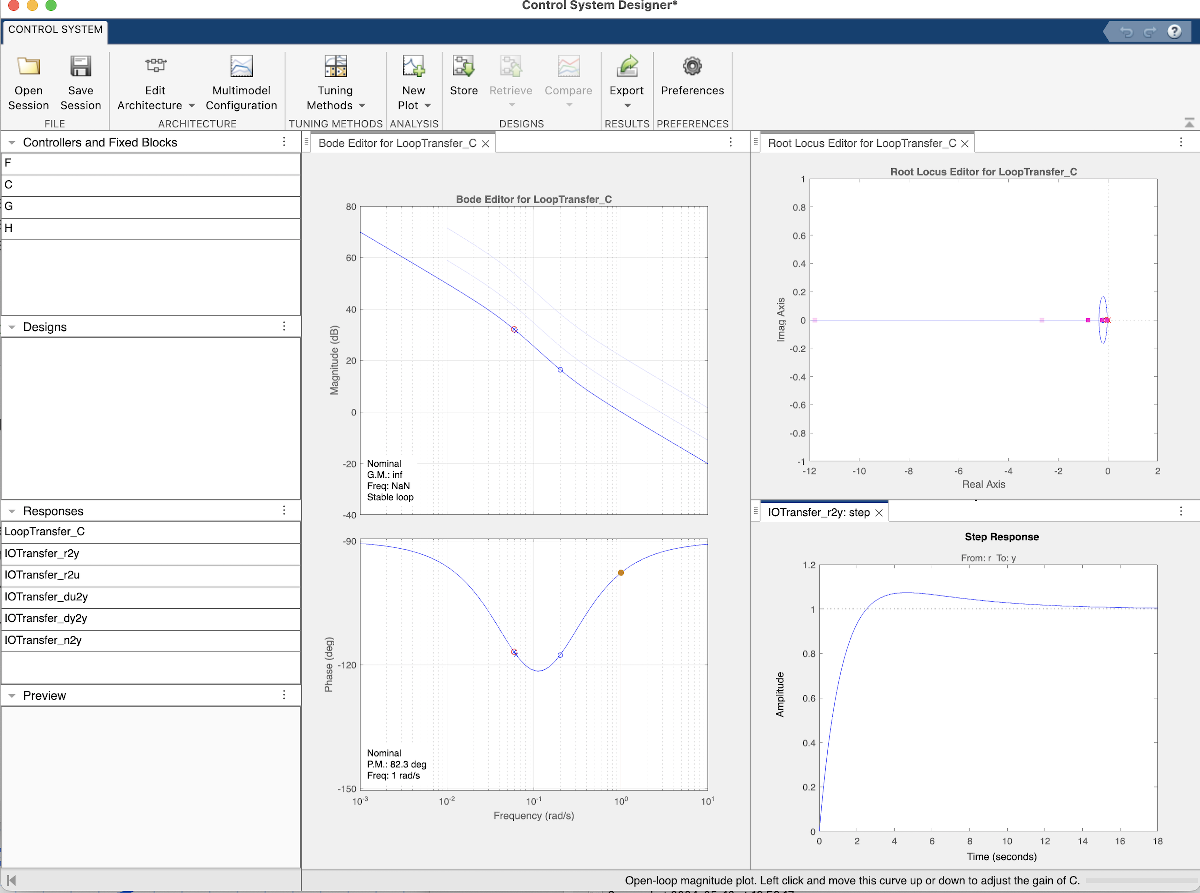

You will find the **session data** corresponding to the above Figure in the MAT file named `CDS_uncertainGain_multimodel.MAT`	

**The Nominal Model**

For details on the **Multimodel Control Design**, refer to the [MATLAB online documentation](https://it.mathworks.com/help/control/ug/design-compensator-for-multiple-plant-models.html).

The *nominal model* is a representative model in the array of LTI models that you use to design the controller in Control System Designer. Use the editor and analysis plots to visualize and analyze the effect of the controller on the remaining plants in the array.

You can select **any model** in the array as your **nominal** **model**. For example, you can choose a model that:

- Represents the expected nominal operating point of your system.

- Is an average of the models in the array.

- Represents **a worst-case plan**t.

[Excerpt from the [MATLAB online documentation](https://it.mathworks.com/help/control/ug/design-compensator-for-multiple-plant-models.html) ]

Selecting the "nominal model" in the *Control System Designer*

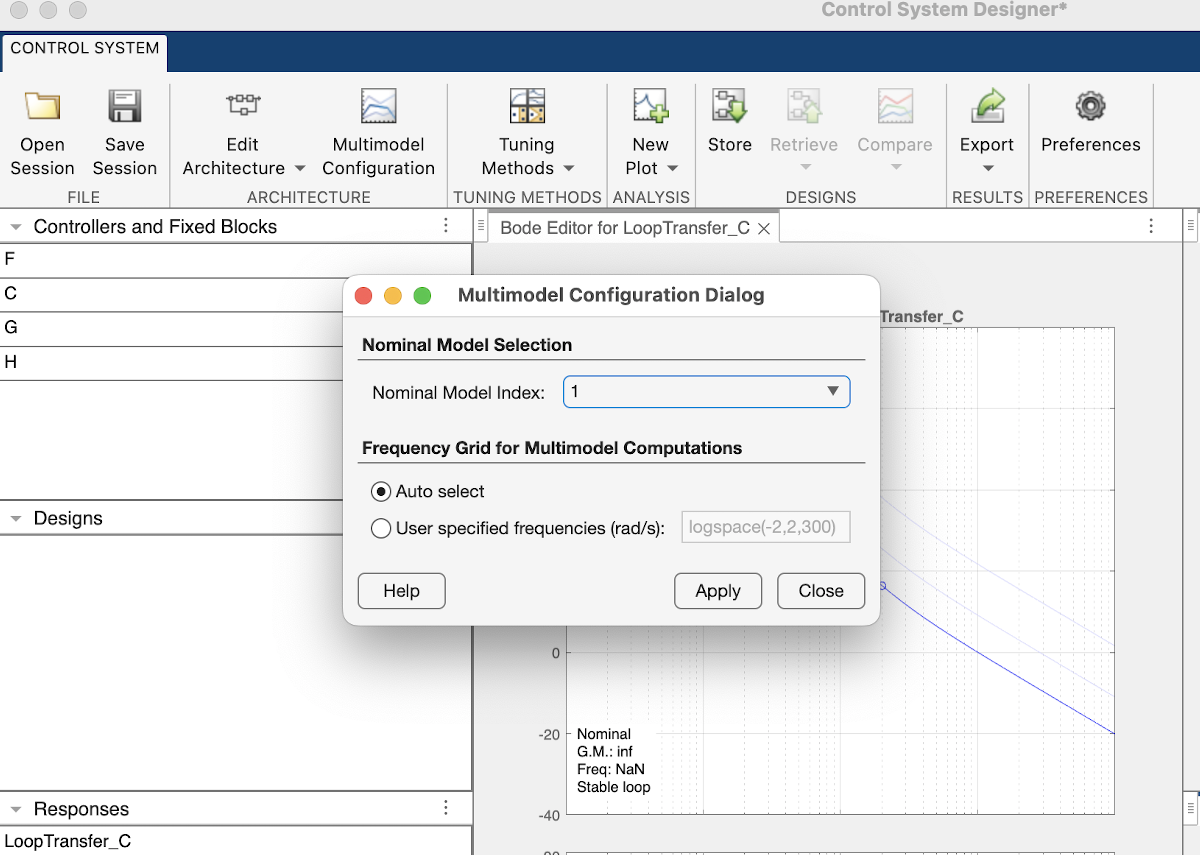

Let's insert the phase margin requirement (Q1.2):

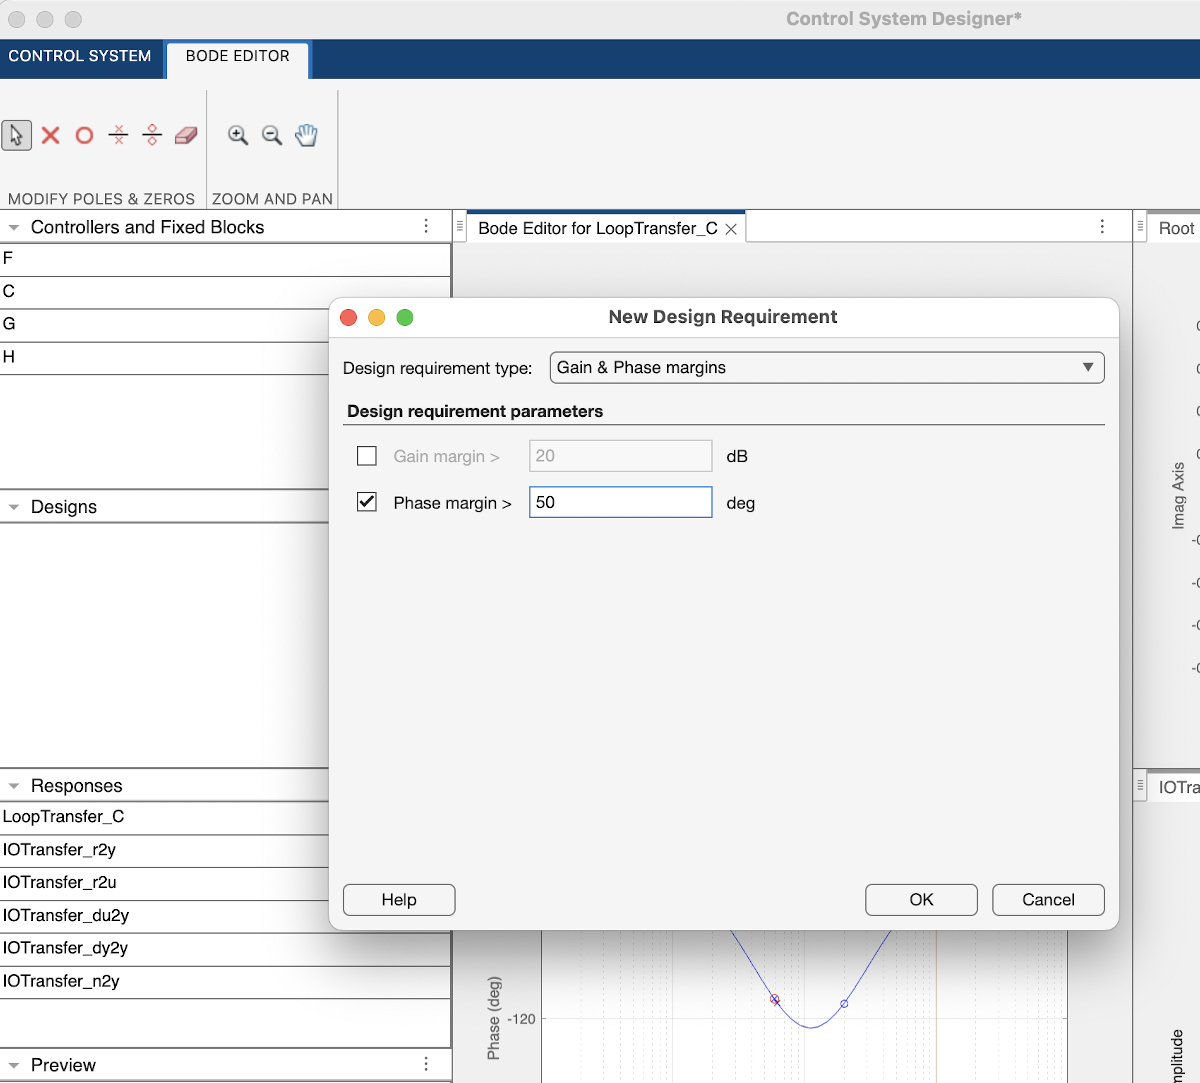

**The multimodel representation in the Bode Editor: **the individual responses

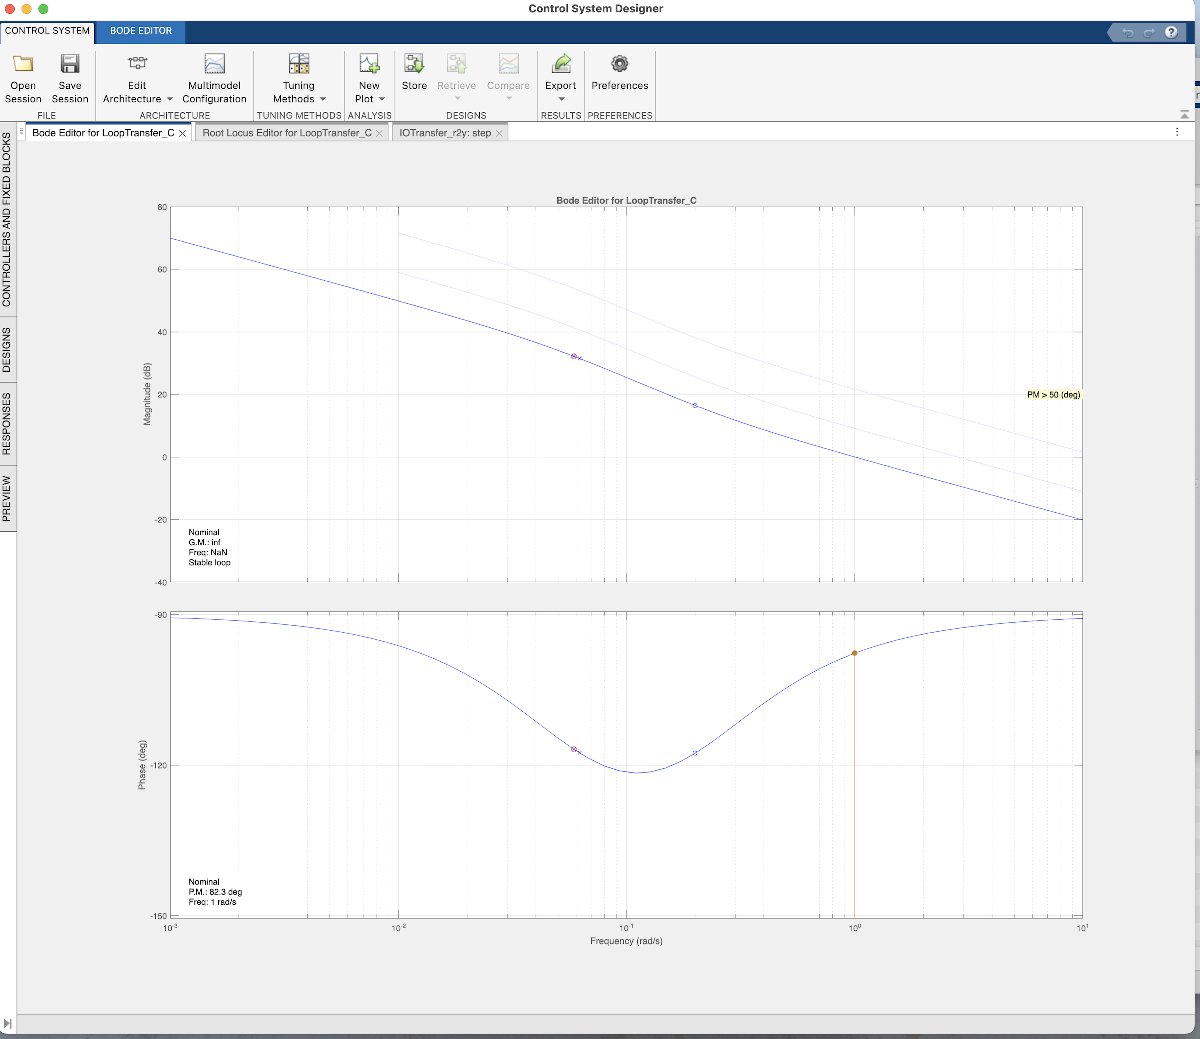

**The multimodel representation in the Bode Editor: **the **bounds** (to view an envelope of all model responses):

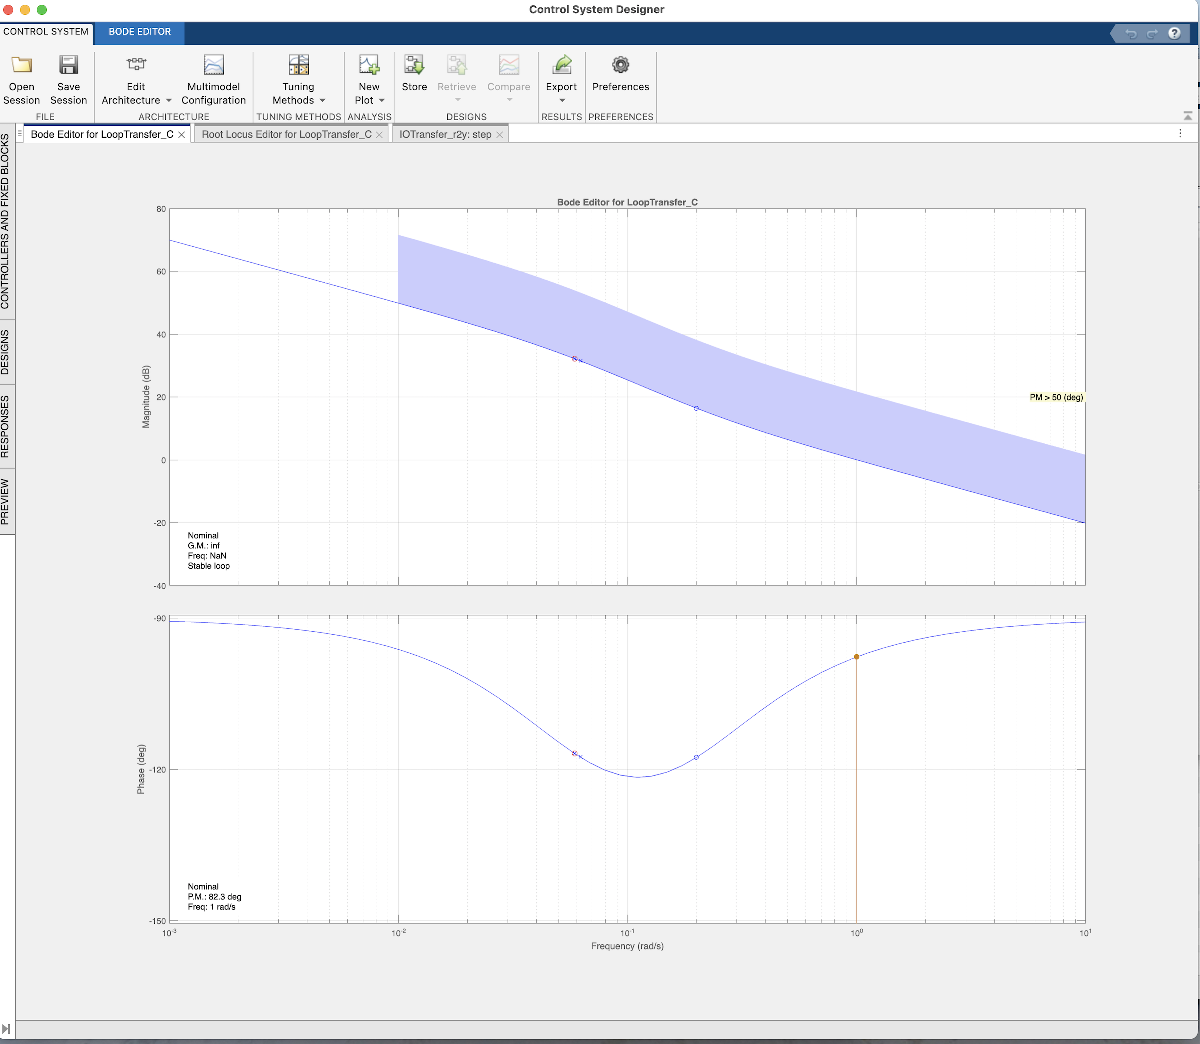

**The multimodel representation in the Step Response Editor: **the individual responses

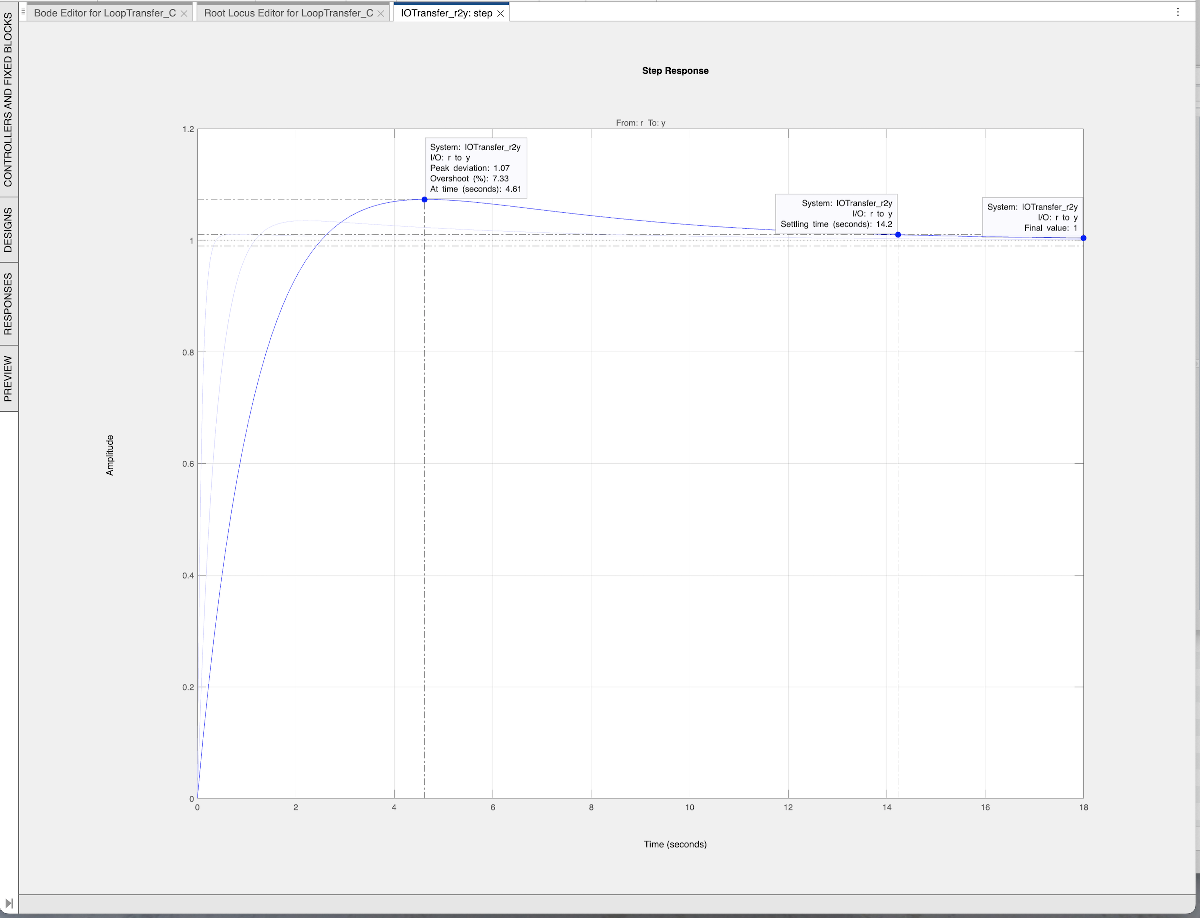

**The multimodel representation in the Step Response Editor: **the **bounds** (to view an envelope of all model responses):

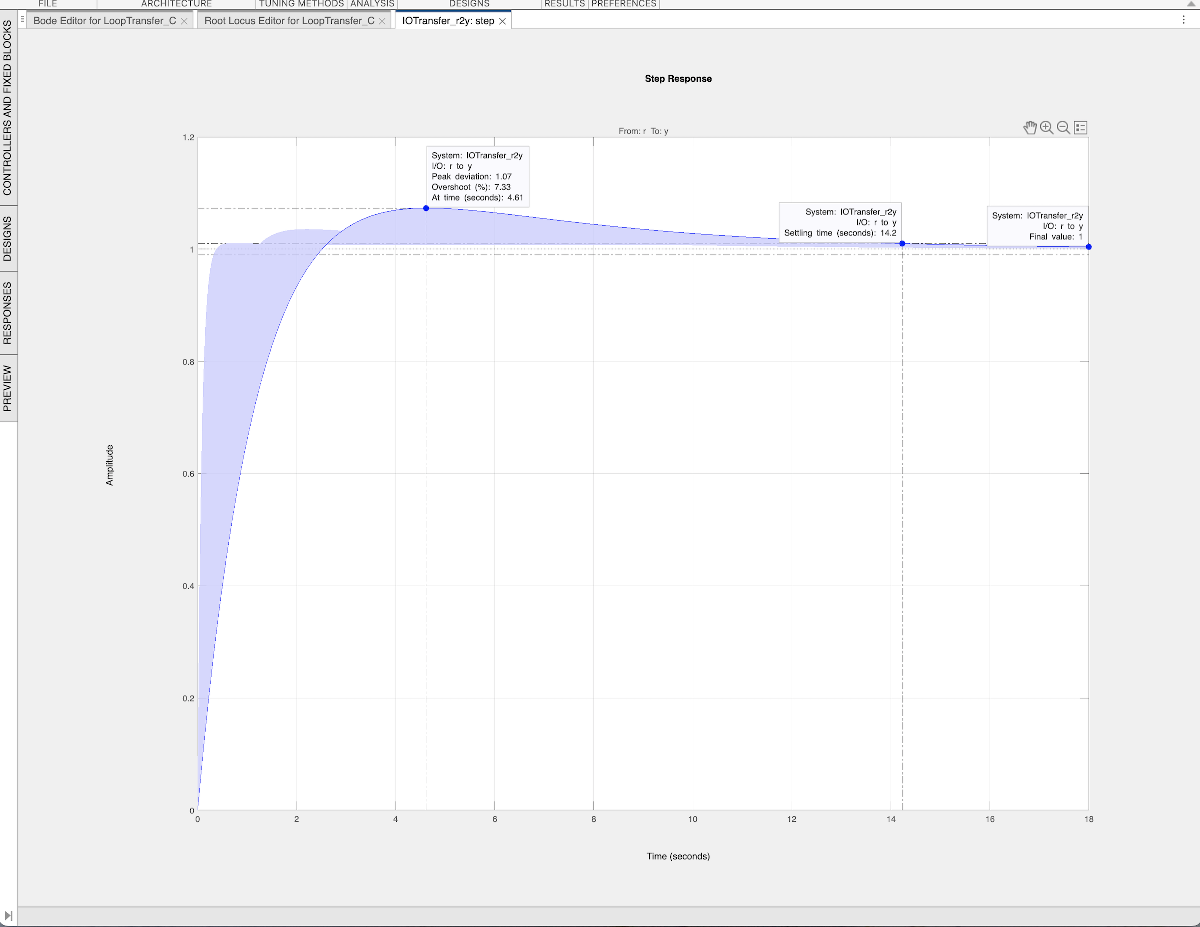

### Final Remark

The controller


$$C(s) = 8.98\,\frac{1+17\,s}{s}$$


meets all the requirements, whatever will be the gain $\mu_G$ of the process $G(s)$ in the given interval $\mu_G \in \left[0.35\,,\; 4.25 \right]$.